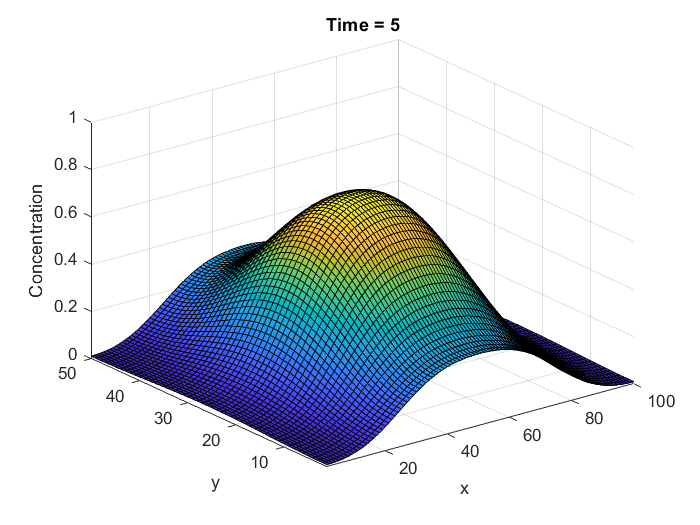

% Parameters
Lx = 10; % Length of the rectangular water bath in x-direction (units)
Ly = 5; % Length of the rectangular water bath in y-direction (units)
Nx = 100; % Number of grid points in x-direction
Ny = 50; % Number of grid points in y-direction
D = 0.1; % Diffusion coefficient (units^2/time)
T = 5; % Total time for simulation (time)

% Discretization
dx = Lx / (Nx - 1); % Grid spacing in x-direction
dy = Ly / (Ny - 1); % Grid spacing in y-direction
dt = 0.01; % Time step
Nt = round(T / dt); % Number of time steps

% Initial condition
u = zeros(Nx, Ny); % Concentration matrix
u(round(Nx/4):round(3*Nx/4), round(Ny/4):round(3*Ny/4)) = 1; % Initial concentration

% Time-stepping loop
for n = 1:Nt
    % Update concentration using forward finite difference in time and central finite difference in space
    for i = 2:Nx-1
        for j = 2:Ny-1
            u(i, j) = u(i, j) + dt * D * (u(i+1, j) - 2*u(i, j) + u(i-1, j)) / dx^2 ...
                + dt * D * (u(i, j+1) - 2*u(i, j) + u(i, j-1)) / dy^2;
        end
    end
    
    % Boundary conditions: zero flux on all boundaries
    u(1,:) = u(2,:);
    u(Nx,:) = u(Nx-1,:);
    u(:,1) = u(:,2);
    u(:,Ny) = u(:,Ny-1);
    
    % Plot concentration distribution
    surf(u');
    xlabel('x');
    ylabel('y');
    zlabel('Concentration');
    title(['Time = ' num2str(n*dt)]);
    axis([1 Nx 1 Ny 0 1]);
    view(3);
    drawnow;
end